# Lab 2

## 1

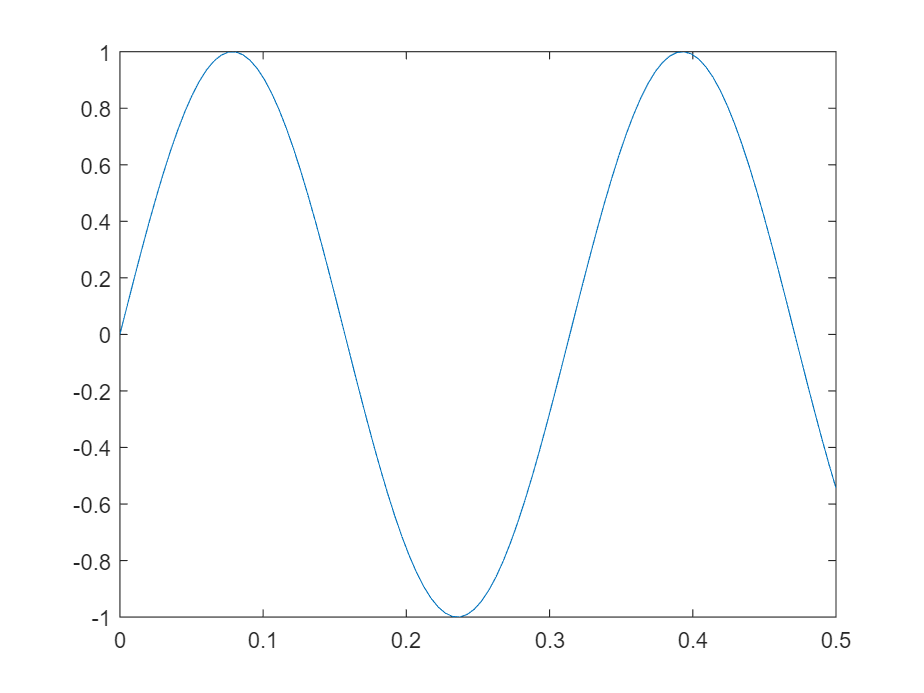

tc=linspace(0,0.5);
xc=sin(20*tc);
td=[0:0.01:0.5];
xd=sin(20*td);

figure(1);
plot(tc,xc);

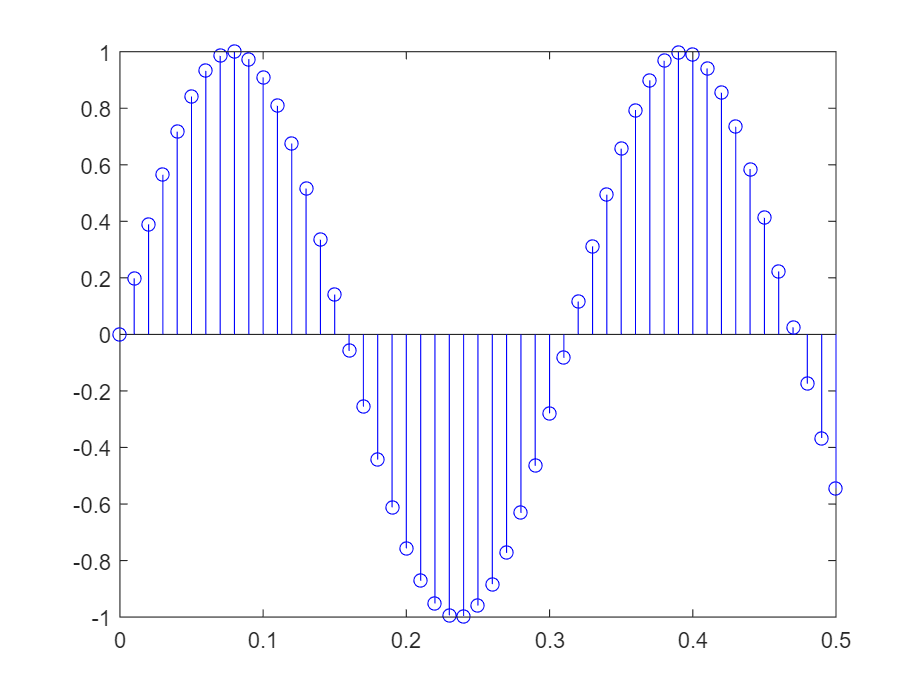


figure(2);
stem(td,xd,'b');hold on;

## 2

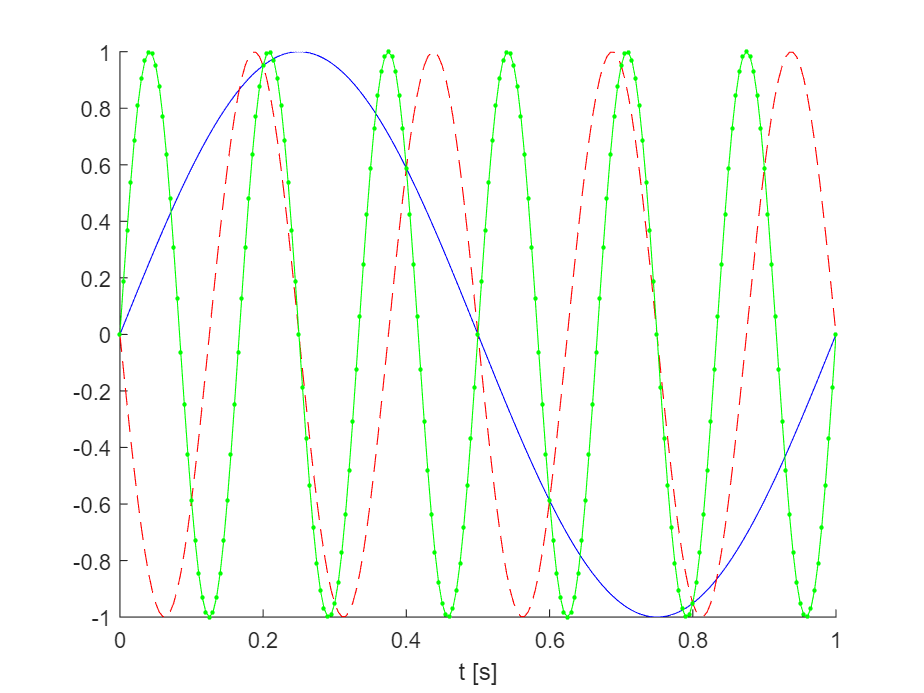

figure(3);
fs = 200; % sampling frequency
t=0:(1/fs):1; % time vector
%
A = 1; % amplitude
phi = 0; % phase
phi2=pi;
f1 =1;% frequency of the signal
f2=4;
f3=6;
% generate and plot waveforms
x1 = A*sin(2*pi*f1*t + phi);
x2 = A*sin(2*pi*f2*t + phi2);
x3 = A*sin(2*pi*f3*t + phi);
xlabel('t [s]');hold on;
plot(t,x1,'-b');
plot(t,x2,'--r');
plot(t,x3,'-g.');
hold off;

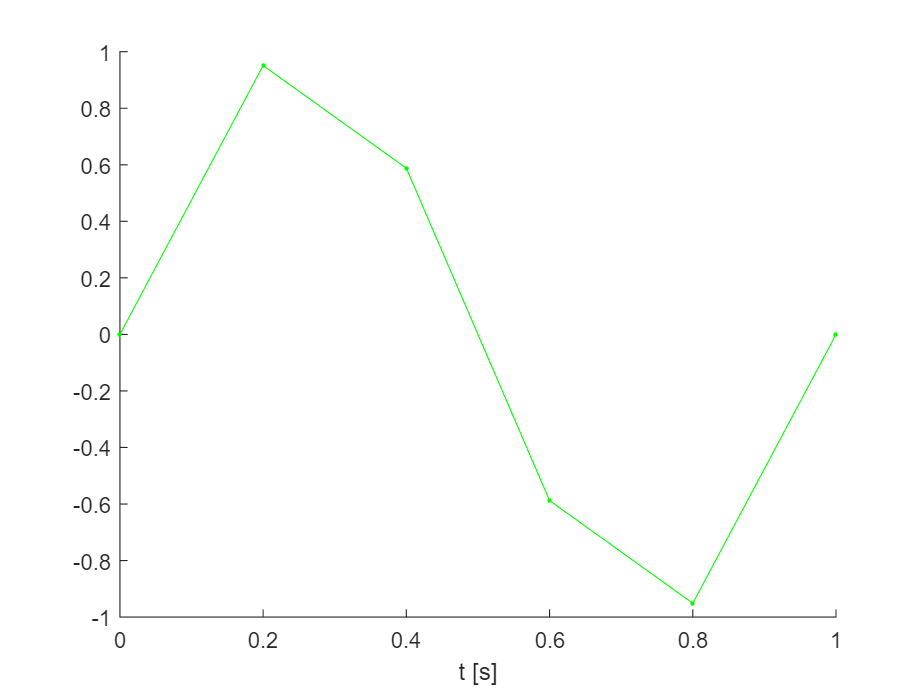




figure(4);
fs = 5; % sampling frequency
t=0:(1/fs):1; % time vector
%
A = 1; % amplitude
phi = 0; % phase

f1 =1;% frequency of the signal
f2=4;
f3=6;
% generate and plot waveforms
x1 = A*sin(2*pi*f1*t + phi);
x2 = A*sin(2*pi*f2*t + phi2);
x3 = A*sin(2*pi*f3*t + phi);
xlabel('t [s]');hold on;
plot(t,x1,'-b');
plot(t,x2,'--r');
plot(t,x3,'-g.');
hold off;

### We can see a degeneration of signal.

## 3

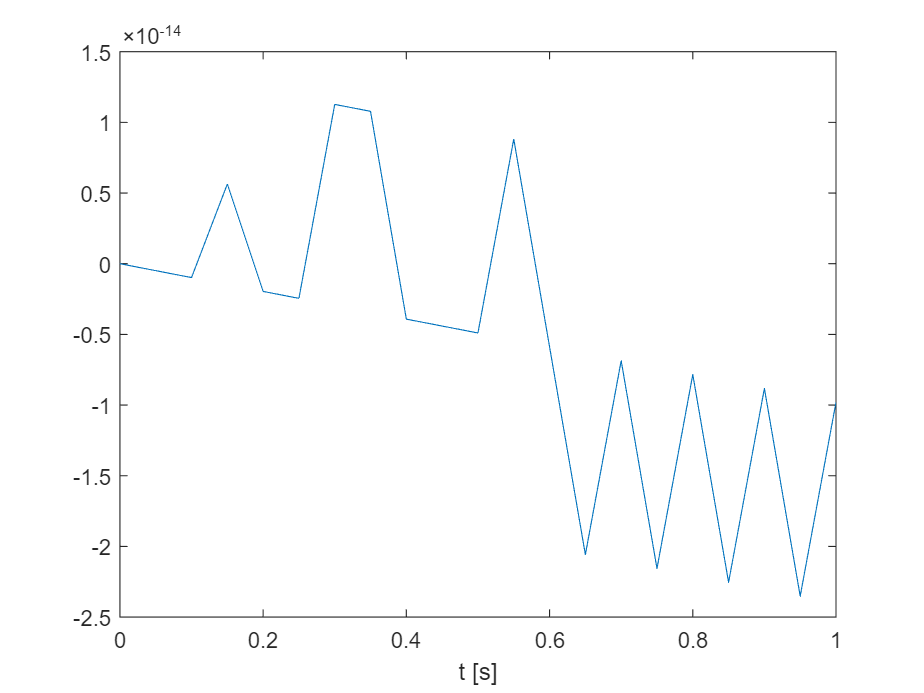

fs = 20; % sampling frequency
t=0:(1/fs):1; % time vector
%
A = 1; % amplitude
phi = 0; % phase
f =40; % frequency of the signal
%
% generate and plot waveforms
x = A*sin(2*pi*f*t + phi);
figure(5), plot(t,x);
xlabel('t [s]');hold on;
hold off;

## 4

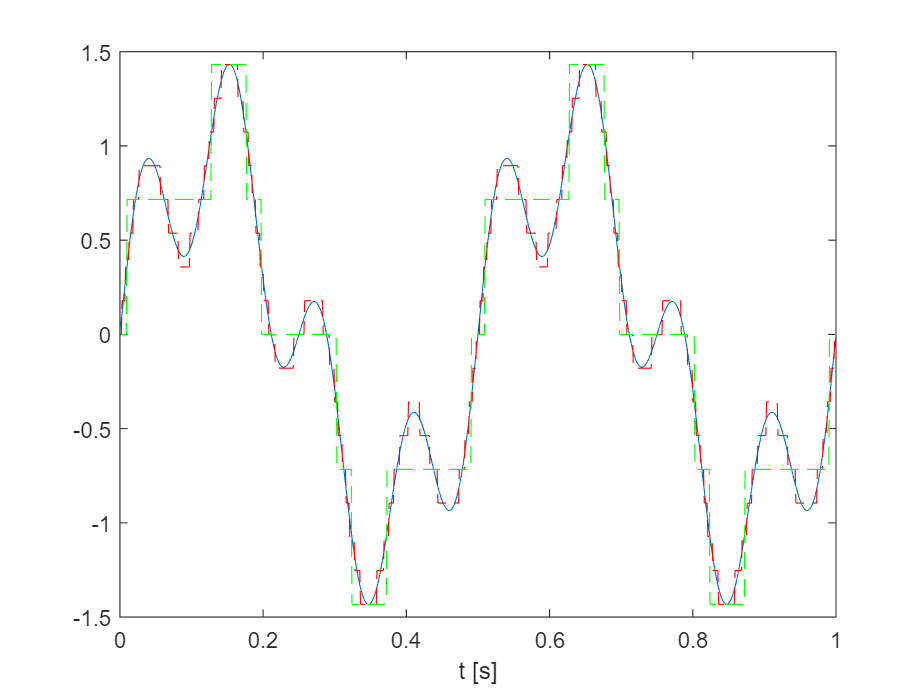

fs = 1000; % sampling frequency
t=0.001:(1/fs):1; % time vector

A = 1; % amplitude
A1=0.5;
phi = 0; % phase
f =2;% frequency of the signal
f1=8; 
%
% generate and plot waveforms
x = A*sin(2*pi*f*t + phi)+A1*sin(2*pi*f1*t + phi);
figure(6), plot(t,x)
xlabel('t [s]');hold on;

range=max(x)-min(x);
dx=range/16;
dx2=range/4;
xq=dx*round(x/dx);
xq2=dx2*round(x/dx2);

plot(t,xq,'--r');
plot(t,xq2,'--g');
hold off;

## 5

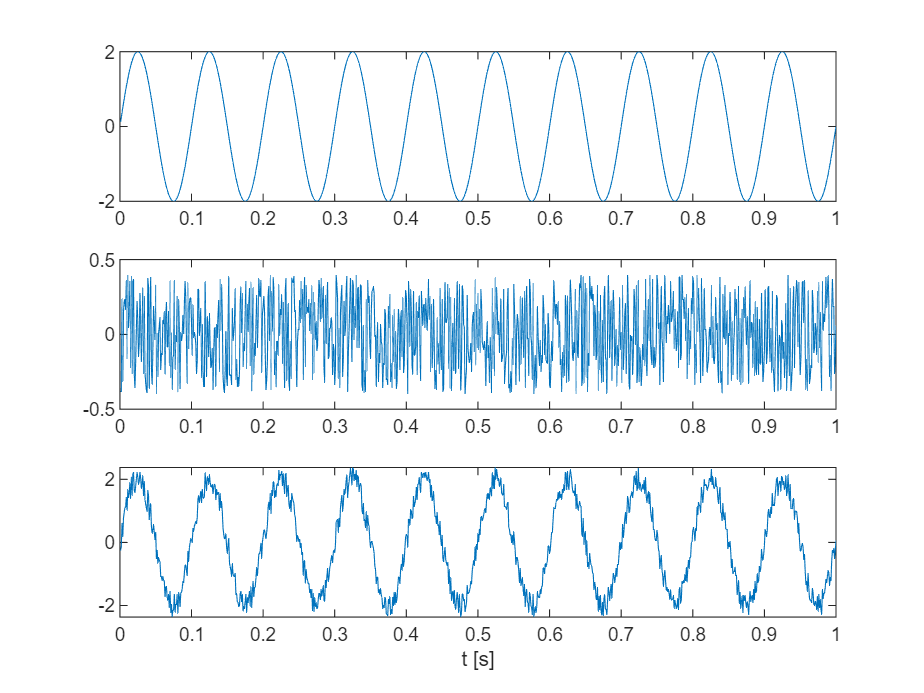

fs = 1000; % sampling frequency
t=0.001:(1/fs):1; % time vector
%
A = 2; % amplitude
phi = 0; % phase
f =10; % frequency of the signal
%
% generate and plot waveforms
x = A*sin(2*pi*f*t + phi);
r = -0.2*A + 2*0.2*A*rand(1,1000);
figure(7), subplot(3,1,1);
plot(t,x);
subplot(3,1,2);
plot(t,r);
subplot(3,1,3);
plot(t,x+r);
xlabel('t [s]');hold on;


hold off;

disp('average value>>');disp(mean(r+x));

average value>>
    0.0041



disp('max val>>');disp(max(x+r));

max val>>
    2.3755



disp('minval>>');disp(min(r+x));

minval>>
   -2.3681



disp('std>>');disp(std(x+r));

std>>
    1.4292



disp('var>>');disp(var(r+x));

var>>
    2.0426



disp('energy>>');disp(sum((x+r).^2));

energy>>
   2.0406e+03



%signalpower=1/(2*1000+1)*sum((x+r).^2);

energy=sum((x+r).^2);
signalpower=energy/length(t);
disp('Power>>');disp(signalpower);

Power>>
    2.0406



%noisepower=1/(2*1000+1)*sum((r).^2);
disp('SNR>>');disp(snr(x+r));

SNR>>
   16.4556

